clear;
x1 = linspace(0,1,3);
x2 = linspace(0,1,3);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);


s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

iPar.mesh     = mesh;
iPar.quadType = 'QUADRATICMASS';
error         = IntegratorError(iPar);

Let's create now a Kernel filter based in Clément interpolators:

ss.filterType = 'AugmentedKernel';
ss.mesh       = mesh;
ss.test       = P0Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
filter        = Filter.create(ss);

ans = ans(:,:,1) =

     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1
     1
     0
     0


ans(:,:,2) =

     1
     1
     0
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     1
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     1


ans = ans(:,:,1) =

     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1
     1
     0
     0


ans(:,:,2) =

     1
     1
     0
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     1
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     1


ans = ans(:,:,1) =

     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1
     1
     0
     0


ans(:,:,2) =

     1
     1
     0
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     1
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     1


ans = ans(:,:,1) =

     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1
     1
     0
     0


ans(:,:,2) =

     1
     1
     0
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     1
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     1


ans = ans(:,:,1) =

     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1
     1
     0
     0


ans(:,:,2) =

     1
     1
     0
     0
     1
     1
     0
     0
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     1
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     1
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     1


ans = ans(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,2) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans = ans(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,2) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans = ans(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,2) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans = ans(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,2) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans = ans(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,2) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,3) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1


ans(:,:,4) =

     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0
     1


ans(:,:,5) =

     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1


ans(:,:,6) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans(:,:,7) =

     0
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1


ans(:,:,8) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


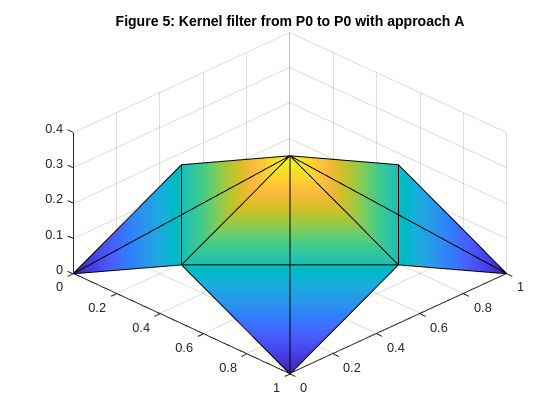

fP0P0A        = filter.compute(fun,'QUADRATICMASS');
fP0P0A.plot()
view(45,45)
title('Figure 5: Kernel filter from P0 to P0 with approach A')

error.compute(fP0P0A,fun)

ans = 0.0532